%% Rocker-Bogie Multi-Phase Kinematic Analysis (2D Traverse)
%
% This script simulates the rover climbing a 0.3m step in three distinct
% phases, using fsolve to determine the constrained chassis pivot position
% (P') and visualizing the resulting link angles.
%
% Constraints:
% 1. Distance between P' and Middle Wheel (M') must equal the Rocker length (L_r).
% 2. Distance between P' and Front Wheel (F') must remain constant (L_PF).

clc; clear; close all;

%% SECTION 1: SYSTEM PARAMETERS AND INITIAL GEOMETRY (INPUTS)
% --- Physical Dimensions (in meters) ---
L_wd = 0.5;   % Wheel Diameter (used for radius)
L_r  = 0.72;  % Rocker Link Length (P to M)
L_span = 0.8; % Horizontal Spacing between Wheel Centers (F-M and M-R)
H_obs = 0.3;  % Height of the Step (30 cm)

% Calculated Values
r = L_wd / 2; % Wheel Radius (0.25 m)
P_initial = [L_span; L_r + r]; % Initial Chassis Pivot P (Flat Ground) [0.8; 0.97]
F_flat = [0.0; r]; % Initial Front Wheel Center
L_PF = sqrt((P_initial(1) - F_flat(1))^2 + (P_initial(2) - F_flat(2))^2); % Fixed P-F Distance

disp(['Starting Multi-Phase Traverse Simulation (H_obs = ' num2str(H_obs) ' m)...']);

Starting Multi-Phase Traverse Simulation (H_obs = 0.3 m)...


disp(['Rocker Length (L_r): ' num2str(L_r) ' m']);

Rocker Length (L_r): 0.72 m


disp(['Fixed P-F Distance (L_PF): ' num2str(L_PF, '%.3f') ' m']);

Fixed P-F Distance (L_PF): 1.076 m


disp('--------------------------------------------------');

--------------------------------------------------




%% SECTION 2: INVERSE KINEMATICS SETUP (3 PHASES)

% Store results in a structure array
results = struct('name', {}, 'P_prime', {}, 'theta_r_deg', {}, 'theta_b_deg', {});
options = optimset('Display', 'off'); % Suppress fsolve output

% --- Phase 1: Front Wheel Climbing (F on step, M and R on ground) ---
M_prime_1 = [L_span; r];
F_prime_1 = [0.0; H_obs + r];
R_prime_1 = [2 * L_span; r];

fun1 = @(X) [
    (X(1) - M_prime_1(1))^2 + (X(2) - M_prime_1(2))^2 - L_r^2; % P' to M' = L_r
    (X(1) - F_prime_1(1))^2 + (X(2) - F_prime_1(2))^2 - L_PF^2  % P' to F' = L_PF
];
P_prime_1 = fsolve(fun1, P_initial, options);


% --- Phase 2: Middle Wheel Climbing (F and M on step, R on ground) ---
% The chassis has moved forward L_span horizontally relative to the step's edge.
% We solve for the ideal P' assuming the linkage constraints hold relative to the
% new wheel contact points.
M_prime_2 = [L_span; H_obs + r];
F_prime_2 = [0.0; H_obs + r]; % F' still holds its height
R_prime_2 = [2 * L_span; r]; % R' still on flat ground

fun2 = @(X) [
    (X(1) - M_prime_2(1))^2 + (X(2) - M_prime_2(2))^2 - L_r^2;
    (X(1) - F_prime_2(1))^2 + (X(2) - F_prime_2(2))^2 - L_PF^2
];
P_prime_2 = fsolve(fun2, P_prime_1, options); % Use Phase 1 result as initial guess


% --- Phase 3: Rear Wheel Climbing (F, M, and R on step) ---
% All three wheel centers are now lifted by H_obs. The chassis should return to
% the initial flat-ground configuration, just translated vertically.
M_prime_3 = [L_span; H_obs + r];
F_prime_3 = [0.0; H_obs + r];
R_prime_3 = [2 * L_span; H_obs + r]; % R' is now on the step, lifted by H_obs

% **FIX: Use fsolve for Phase 3 for consistency and robustness**
fun3 = @(X) [
    (X(1) - M_prime_3(1))^2 + (X(2) - M_prime_3(2))^2 - L_r^2; % P' to M' = L_r
    (X(1) - F_prime_3(1))^2 + (X(2) - F_prime_3(2))^2 - L_PF^2  % P' to F' = L_PF
];
% Use Phase 2 result as initial guess
P_prime_3_guess = P_initial + [L_span; H_obs]; % A better guess for Phase 3
P_prime_3 = fsolve(fun3, P_prime_2, options); % Use fsolve


% --- Aggregate and Calculate Angles for All Phases ---
P_list = {P_prime_1, P_prime_2, P_prime_3};
F_list = {F_prime_1, F_prime_2, F_prime_3};
M_list = {M_prime_1, M_prime_2, M_prime_3};
R_list = {R_prime_1, R_prime_2, R_prime_3};
names = {'Phase 1 (F up)', 'Phase 2 (M up)', 'Phase 3 (R up)'};

for i = 1:3
    P = P_list{i}; F = F_list{i}; M = M_list{i}; R = R_list{i};

    % Rocker Angle (P to M) - Angle of P->M vector relative to horizontal
    theta_r_rad = atan2(M(2) - P(2), M(1) - P(1));
    theta_r_deg = rad2deg(theta_r_rad);

    % Bogie Angle (F to R) - Angle of F->R vector relative to horizontal
    theta_b_rad = atan2(R(2) - F(2), R(1) - F(1));
    theta_b_deg = rad2deg(theta_b_rad);
    
    % Store results
    results(i).name = names{i};
    results(i).P_prime = P;
    results(i).theta_r_deg = theta_r_deg;
    results(i).theta_b_deg = theta_b_deg;
    results(i).F_coords = F;
    results(i).M_coords = M;
    results(i).R_coords = R;

    % Output Summary
    disp(['--- ' names{i} ' ---']);
    disp(['P'': (' num2str(P(1), '%.3f') ', ' num2str(P(2), '%.3f') ')']);
    disp(['Chassis Rise: ' num2str((P(2) - P_initial(2)) * 100, '%.1f') ' cm']);
    disp(['theta_r: ' num2str(theta_r_deg, '%.1f') ' deg, theta_b: ' num2str(theta_b_deg, '%.1f') ' deg']);
end

--- Phase 1 (F up) ---


P': (1.003, 0.941)


Chassis Rise: -2.9 cm


theta_r: -106.4 deg, theta_b: -10.6 deg


--- Phase 2 (M up) ---


P': (0.800, 1.270)


Chassis Rise: 30.0 cm


theta_r: -90.0 deg, theta_b: -10.6 deg


--- Phase 3 (R up) ---


P': (0.800, 1.270)


Chassis Rise: 30.0 cm


theta_r: -90.0 deg, theta_b: 0.0 deg


disp('--------------------------------------------------');

--------------------------------------------------


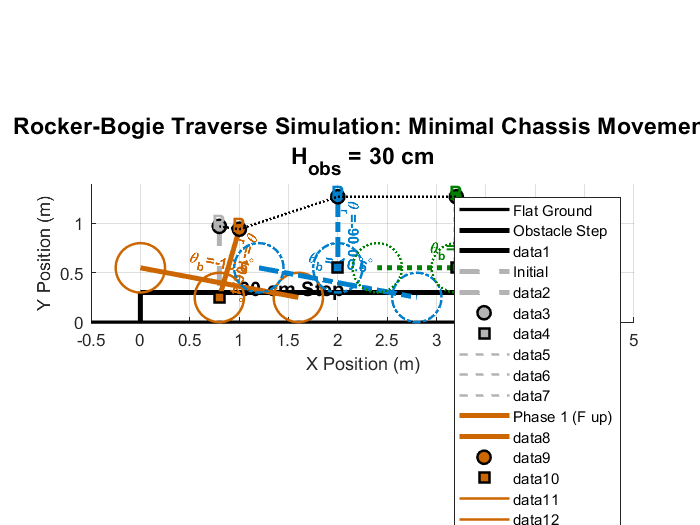



%% SECTION 3: VISUALIZATION (Multi-Phase Plot)

figure('Name', 'Rocker-Bogie Traverse Simulation');
hold on;
axis equal;
grid on;

% --- 3.1 Terrain Plotting (Longer Step) ---
plot([-0.5, 4.0], [0, 0], 'k-', 'LineWidth', 2, 'DisplayName', 'Flat Ground'); % Flat Ground
plot([0, 0], [0, H_obs], 'k-', 'LineWidth', 3, 'DisplayName', 'Obstacle Step');  % Vertical face
plot([0, 4.0], [H_obs, H_obs], 'k-', 'LineWidth', 3); % Top face of the step

text(1.0, H_obs + 0.05, [num2str(H_obs*100) ' cm Step'], 'Color', 'k', 'FontSize', 12, 'FontWeight', 'bold');

% --- Color mapping for phases ---
colors = {[0.7 0.7 0.7], [0.8 0.4 0], [0 0.5 0.8], [0 0.5 0]}; % Initial (Gray), Phase 1 (Orange), Phase 2 (Blue), Phase 3 (Green)
styles = {'--', '-', '-.', ':'};
initial_P = P_initial;
P_path_coords = [P_initial];

% --- Draw Initial (Flat) Configuration (reference) ---
draw_rover_fcn(P_initial, F_list{1}, M_list{1}, R_list{1}, colors{1}, styles{1}, 'Initial', r, 0, 0, 0);

% --- Draw All Three Phases (Shifted to show traverse) ---
for i = 1:3
    P = results(i).P_prime;
    F = results(i).F_coords;
    M = results(i).M_coords;
    R = results(i).R_coords;
    theta_r = results(i).theta_r_deg;
    theta_b = results(i).theta_b_deg;
    
    % Horizontal displacement to represent forward motion
    x_shift = (i - 1) * L_span * 1.5; % Use 1.5*L_span for clearer separation
    
    P_shifted = P + [x_shift; 0];
    F_shifted = F + [x_shift; 0];
    M_shifted = M + [x_shift; 0];
    R_shifted = R + [x_shift; 0];
    
    % Draw the shifted configuration
    draw_rover_fcn(P_shifted, F_shifted, M_shifted, R_shifted, colors{i+1}, styles{i+1}, results(i).name, r, theta_r, theta_b, i);

    % Update P path for plotting
    P_path_coords(:, end+1) = P_shifted;
end

% Draw path of the chassis pivot (P)
plot(P_path_coords(1, 1:end), P_path_coords(2, 1:end), 'k:', 'LineWidth', 1.5, 'DisplayName', 'Chassis P Path');


% --- 3.4 Final Plot Settings ---
title({'Rocker-Bogie Traverse Simulation: Minimal Chassis Movement', ...
        ['H_{obs} = ' num2str(H_obs*100) ' cm']}, 'FontSize', 14);
xlabel('X Position (m)');
ylabel('Y Position (m)');
xlim([-0.5, 5.0]);
ylim([0, 1.4]);
legend('Location', 'northeast');
hold off;



%% HELPER FUNCTIONS
% Function to draw the rover configuration, including links, wheels, and angle labels.

function draw_rover_fcn(P, F, M, R, color, style, label, r, theta_r_deg, theta_b_deg, phase_num)
    
    % --- Draw Links ---
    % Rocker Link (P to M)
    plot([P(1), M(1)], [P(2), M(2)], 'Color', color, 'LineWidth', 3, 'LineStyle', style, 'DisplayName', [label]);
    
    % Bogie Link (F to R) - simplified straight line
    plot([F(1), R(1)], [F(2), R(2)], 'Color', color, 'LineWidth', 3, 'LineStyle', style);

    % --- Angle Labels (Only for the Phase Configs) ---
    if phase_num ~= 0
        % Rocker Angle Label (Midpoint of P' to M')
        rocker_mid_x = (P(1) + M(1)) / 2;
        rocker_mid_y = (P(2) + M(2)) / 2;
        text(rocker_mid_x, rocker_mid_y, ['\theta_r=' num2str(theta_r_deg, '%.1f') '^\circ'], ...
             'Color', color, 'FontSize', 9, 'FontWeight', 'bold', 'Rotation', theta_r_deg, ...
             'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
          
        % Bogie Angle Label (Midpoint of F' to R')
        bogie_mid_x = (F(1) + R(1)) / 2;
        bogie_mid_y = (F(2) + R(2)) / 2;
        text(bogie_mid_x, bogie_mid_y + 0.05, ['\theta_b=' num2str(theta_b_deg, '%.1f') '^\circ'], ...
             'Color', color, 'FontSize', 9, 'FontWeight', 'bold', 'Rotation', theta_b_deg, ...
             'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
    end

    % --- Draw Pivots and Joints ---
    plot(P(1), P(2), 'o', 'MarkerSize', 8, 'MarkerFaceColor', color, 'Color', 'k', 'LineWidth', 1.5);
    plot(M(1), M(2), 's', 'MarkerSize', 8, 'MarkerFaceColor', color, 'Color', 'k', 'LineWidth', 1.5);

    % Draw Wheels (Simplified Circles)
    th = linspace(0, 2*pi, 50);
    wheel_x = [F(1), M(1), R(1)];
    wheel_y = [F(2), M(2), R(2)];
    for k = 1:3
        x_wheel = wheel_x(k) + r * cos(th);
        y_wheel = wheel_y(k) + r * sin(th);
        plot(x_wheel, y_wheel, 'Color', color, 'LineWidth', 1.5, 'LineStyle', style);
    end

    % Annotate Pivots
    text(P(1), P(2) + 0.05, 'P', 'Color', color, 'FontSize', 12, 'FontWeight', 'bold', 'HorizontalAlignment', 'center');
end
